## Plot the workspace of the robot

step = 360/20;
nb_points = round(360/step);
%disp(nb_points);
%disp(nb_points^3);
xwork = zeros(nb_points^2) ; % reserving space for the variables, because
ywork = zeros(nb_points^2) ; % otherwise they would be created later within a loop.
zwork = zeros(nb_points^2);
i=1;
q5 = 0;
max = 0;

for q1 = 0:step:360
    for q2 = 0:step:180
        for q3 = -65:step:115
            for q4 = -180:step:0
                L_q = [q1 q2 q3 q4 q5];
                pos = forward_kinematics(L_q);
                if (pos(1)^2+pos(2)^2+pos(3)^2)^0.5 >0
                    max = (pos(1)^2+pos(2)^2+pos(3)^2)^0.5;
                    xwork(i) = pos(1);
                    ywork(i) = pos(2);
                    zwork(i) = pos(3);
                    i = i+1;
                end
            end
        end
    end
end    


figure (3)
set(3,'position')

  0×0 empty cell array



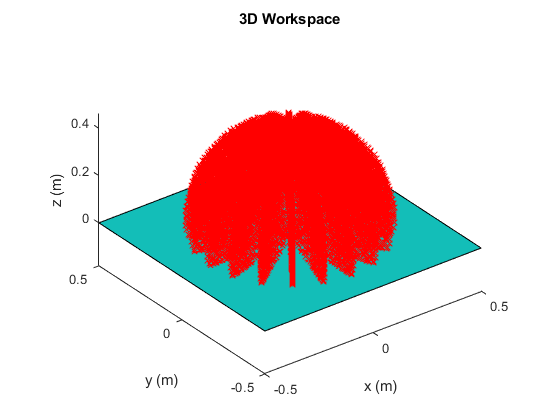

plot3(0,0,0,'o')
hold on
[xp, yp] = meshgrid(-0.5:1:0.5); % Generate x and y data
zp = zeros(size(xp, 1)); % Generate z data
surf(xp, yp, zp) % Plot the surface
plot3(xwork,ywork,zwork,'rx')  % plot the  workspace of the robot
axis equal

title('3D Workspace') ; xlabel('x (m)') ; ylabel('y (m)') ; zlabel('z (m)') ;
hold off

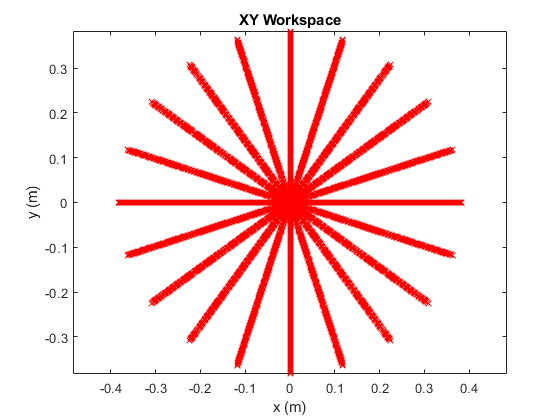



plot(xwork,ywork,'rx')
title('XY Workspace') ; xlabel('x (m)') ; ylabel('y (m)');
axis equal

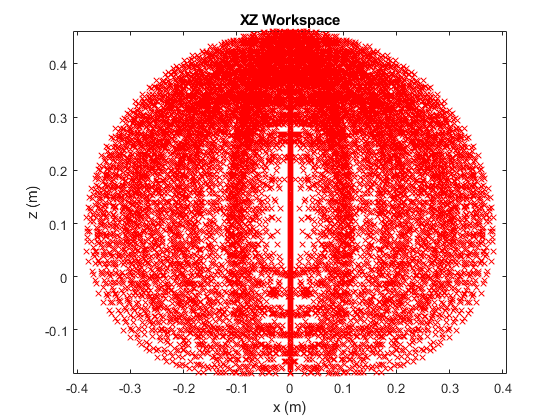




plot(xwork,zwork,'rx')
title('XZ Workspace') ; xlabel('x (m)') ; ylabel('z (m)');
axis equal

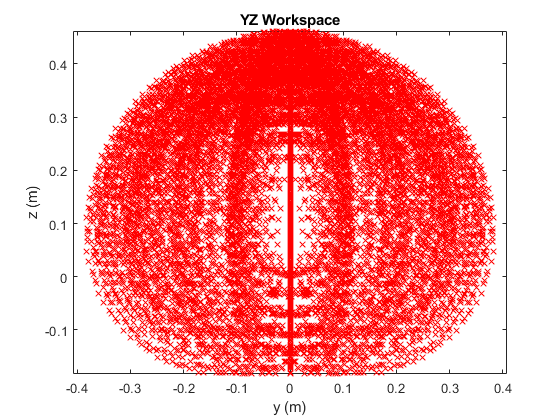



plot(ywork,zwork,'rx')
title('YZ Workspace') ; xlabel('y (m)') ; ylabel('z (m)');
axis equal

## Inverse Kinematics

l_fk=[45 0 25 -90 0];
pos = forward_kinematics(l_fk)

pos =     1.9888    1.9888    1.8452


inv_mat=inverse_kin(1.9888, 1.9888 ,1.845,0,0)
 list = plot_links(inv_mat)

theta_entree = [0 0 0 0 0]

theta_entree =      0     0     0     0     0


list1 =      0     0     1     2     2     2
     0     0     0     0     0     0
     0     1     1     1     1     2


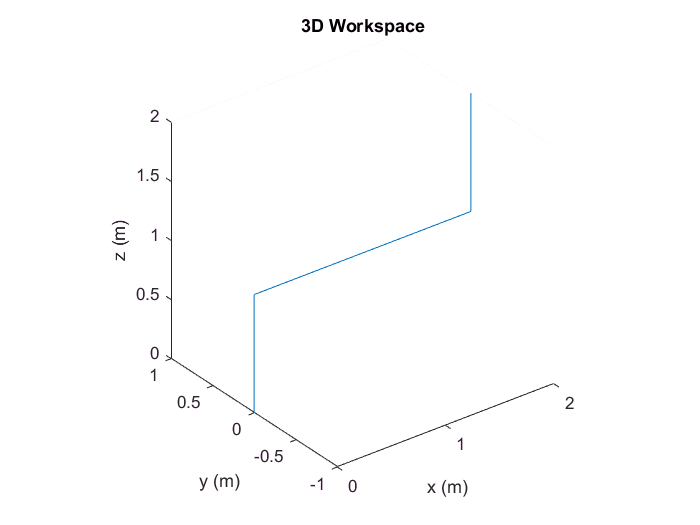


list1 = plot_links(theta_entree)

end_pose = forward_kinematics(theta_entree)

end_pose =      2     0     2     0     0     0


theta_recacule=inverse_kin(end_pose(1), end_pose(2) ,end_pose(3),end_pose(4),end_pose(5))

theta_recacule =      0    90   -90     0     0


theta_offset = theta_recacule;

theta_offset(2) = theta_offset(2) -90;
theta_offset(3) = theta_offset(3) +90

theta_offset =      0     0     0     0     0


list2 =      0     0     1     2     2     2
     0     0     0     0     0     0
     0     1     1     1     1     2



list2 = plot_links(theta_offset)